## Solve the polarity equation

As a fisrt approach, we will solve the polarity equation 


$$L_c^2 \nabla \textrm{²p}\left(\mathit{\mathbf{r}}\right)=p\left(\mathit{\mathbf{r}}\right);\;\mathit{\mathbf{r}}\in \Omega \;\;$$


Thus, the boundary conditions will be


$$p\left(\mathit{\mathbf{r}}\right)\cdot \overrightarrow{n} =1,\;\;\;\;\;\;\mathit{\mathbf{r}}\in \partial \Omega$$


Declare the model parameters

h      =  5.0;  % Monolayer height, μm
T0     =  0.5;  % Maximal traction, kPa, 0.2-0.8
Lc     =  25.0; % Nematic lenght, μm
zeta   = -20.0; % zeta = - Contrtactility, kPa, 5-50
visc   =  50e3; % Monolayer viscosity, kPa·s, 3e3-3e4
R_crit = .5*(3*Lc - zeta*h/T0); % Critical radius
R =  200;  % Tissue radius
h_cell_max = 20;
cut_angle = 3*pi/4;

Declare the PDE system as a system symbolic equations. Extract the coefficients of the PDE and return them in symbolic form.

syms u1(x,y) u2(x,y) % u1 = p_x, u2 = p_y
pdeeq = [laplacian(u1) - u1/Lc^2; laplacian(u2) - u2/Lc^2];
symCoeffs = pdeCoefficients(pdeeq,[u1 u2],'Symbolic',true);
coeffs = pdeCoefficientsToDouble(symCoeffs, pdeeq);

structfun(@disp,symCoeffs) % display coefs: m,a, c, f, d

$$0$$

$$\left(\begin{array}{cc} -\frac{1}{625} & 0\\ 0 & -\frac{1}{625} \end{array}\right)$$

$$\left(\begin{array}{cccc} -1 & 0 & 0 & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & -1 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

$$0$$

Create a geometry for the cutted circle

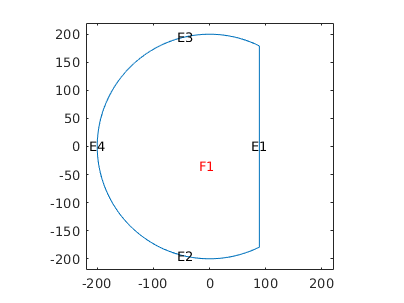

x_cut = R*(1-cos(.5*(pi-.5*cut_angle)));

circle = [1 0 0 R]';

rect = [3 4 x_cut R+1 R+1 x_cut -R -R R R]';

circle = [circle;zeros(length(rect) - length(circle),1)]; %append extra zeros
gd = [circle, rect]; % Combine the shapes into one matrix.
ns = char('circle', 'rect')'; % create names for the shapes
sf = 'circle-rect'; % set formula
circle_cut = decsg(gd, 'circle-rect', ns);
pdegplot(circle_cut, 'EdgeLabels', 'on', 'FaceLabels', 'on')
xlim([-1.1*R, 1.1*R])
ylim([-1.1*R, 1.1*R])

Create a model, specify the coefficients,

model = createpde(2);
geometryFromEdges(model,circle_cut);

specifyCoefficients(model,'m',coeffs.m,'d',coeffs.d, ...
    'c',coeffs.c,'a',coeffs.a,'f',[0,0]');

and apply boundary conditions

applyBoundaryCondition(model,'dirichlet', ...
                             'Edge',1:model.Geometry.NumEdges, ...
                             'u',@normalbc);

Generate and plot the mesh

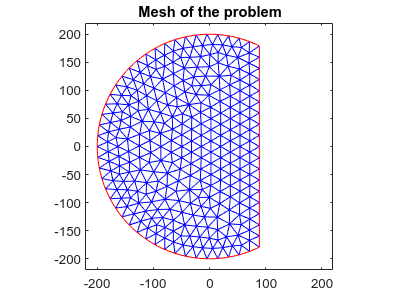

mesh = generateMesh(model,'Hmax',h_cell_max);
figure; 
pdemesh(model); 
xlim([-1.1*R, 1.1*R])
ylim([-1.1*R, 1.1*R])
title 'Mesh of the problem'

Solve the PDE and plot the solution

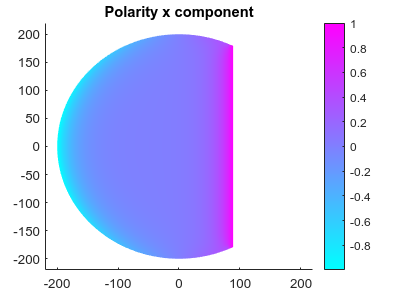

results = solvepde(model);
p = results.NodalSolution;

figure;
pdeplot(model,'XYData',p(:,1))
title 'Polarity x component'
xlim([-1.1*R, 1.1*R])
ylim([-1.1*R, 1.1*R])

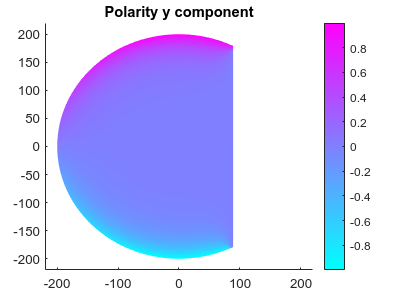


figure;
pdeplot(model,'XYData',p(:,2))
title 'Polarity y component'
xlim([-1.1*R, 1.1*R])
ylim([-1.1*R, 1.1*R])

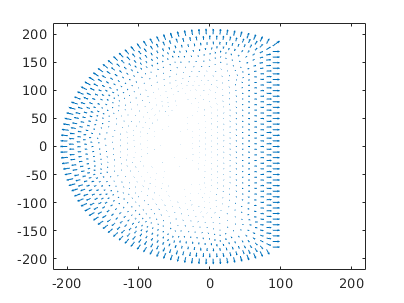


nodes = mesh.Nodes;
figure;
quiver(nodes(1,:)', nodes(2,:)',p(:,1),p(:,2))
xlim([-1.1*R, 1.1*R])
ylim([-1.1*R, 1.1*R])

Create a function that applies the boundary conditions

function bc = normalbc(location,state)
bc = [location.nx, location.ny];
end